根据CAS号, 从数据库中找到对应物质的物性数据

以苯为例子, CAS = 71-43-2

CAS = '71-43-2';
C6H6 = Component(CAS);

- Ename, 英文名字, -

Ename = C6H6.Ename

- Pc, 临界压力, Pa

Pc = C6H6.Pc

- Tc, 临界温度, K

Tc = C6H6.Tc

- Vc, 临界体积, $\frac{m^3 }{\textrm{kmol}}$

Vc = C6H6.Vc

Ename = 'Benzene'

- Zc, 临界压缩因子,  -

Zc = C6H6.Zc

- Tb, 常压沸点温度, K

Tb = C6H6.Tb

- Ttriple, 三相点温度, K

Ttriple = C6H6.Ttriple

Pc =      4895000


- Ptriple, 三相点压力, Pa

Ptriple = C6H6.Ptriple

- Mw, 摩尔质量, $\frac{\textrm{kg}}{\textrm{kmol}}$

Mw = C6H6.Mw

- $\omega \;$, 偏心因子, -

omega = C6H6.omega

Tc =      5.620500000000000e+02


- ${H^m }_{\textrm{form}}$ , 标准摩尔生成焓, $\frac{J}{\textrm{kmol}}$

Hfrom = C6H6.Hform

- ${G^m }_{\textrm{from}}$ , 标准摩尔生成自由能, $\frac{J}{\textrm{kmol}}$

Gform = C6H6.Gform

- LiquidDensity, 液体的密度, kmol/m^3

- 
$$\rho_L =\frac{A}{B^{\left(1+{\left(1-\frac{T}{C}\right)}^D \right)} }$$


Vc =    0.256000000000000


plot([ C6H6.LiquidDensity(end-1):C6H6.LiquidDensity(end) ], C6H6.LiquidDensity_func( [C6H6.LiquidDensity(end-1):C6H6.LiquidDensity(end) ] ))
hold on
plot(450,  C6H6.LiquidDensity_func(450), 'or')

Zc =    0.268000000000000


text(450,  C6H6.LiquidDensity_func(450)+0.5, num2str(C6H6.LiquidDensity_func(450)) )
hold off
title('$${\rho_L-T}$$ Curve', 'Interpreter', 'latex')

Tb =      3.532400000000000e+02


xlabel('T/K')
ylabel('$${ \rho_L/ \frac{kmol}{m^3} }$$', 'Interpreter', 'latex')

- VaporPressure, 饱和蒸汽压, Pa

- 
$$P^* =e^{\left(A+\frac{B}{T}+C*\ln \left(T\right)+D*T^E \right)}$$


plot([ C6H6.VaporPressure(end-1):C6H6.VaporPressure(end) ], C6H6.VaporPressure_func( [C6H6.VaporPressure(end-1):C6H6.VaporPressure(end) ] ))

Ttriple =      2.786800000000000e+02


hold on
plot(450,  C6H6.VaporPressure_func(450), 'or')
text(455,  C6H6.VaporPressure_func(450), num2str(C6H6.VaporPressure_func(450)) )

Ptriple =      4.764220000000000e+03


hold off
title('$${P^*-T}$$ Curve', 'Interpreter', 'latex')
xlabel('T/K')

Mw =   78.114000000000004


ylabel('$${ P^*/Pa }$$', 'Interpreter', 'latex')

- HeatOfVaporization, 标准摩尔蒸发焓, J/kmol

- 
$$\Delta {H^m }_{\textrm{vap}} =A*{\left(1-T_r \right)}^{\left(B+C*T_r +D*T_r^2 +E*T_r^3 \right)} ,T_r =\frac{T}{\textrm{Tc}}$$


plot([ C6H6.HeatOfVaporization(end-1):C6H6.HeatOfVaporization(end) ], C6H6.HeatOfVaporization_func( [C6H6.HeatOfVaporization(end-1):C6H6.HeatOfVaporization(end) ] ))
hold on

omega =    0.209000000000000


plot(450,  C6H6.HeatOfVaporization_func(450), 'or')
text(455,  C6H6.HeatOfVaporization_func(450), num2str(C6H6.HeatOfVaporization_func(450)) )
hold off

Hfrom =     82880000


title('$${\Delta H^m_{vap}-T}$$ Curve', 'Interpreter', 'latex')
xlabel('T/K')
ylabel('$${\Delta H^m_{vap}/ \frac{J}{kmol}}$$', 'Interpreter', 'latex')

Gform =    129600000


- LiquidHeatCapacityCp, 液体等压比热容, J/kmol/K

- 
$${C_{P,L} }^m =A+e^{\left(\frac{B}{T}+C+D*T+E*T^2 \right)}$$


plot([ C6H6.LiquidHeatCapacityCp(end-1):C6H6.LiquidHeatCapacityCp(end) ], C6H6.LiquidHeatCapacityCp_func( [C6H6.LiquidHeatCapacityCp(end-1):C6H6.LiquidHeatCapacityCp(end) ] ))
hold on
plot(450,  C6H6.LiquidHeatCapacityCp_func(450), 'or')
text(455,  C6H6.LiquidHeatCapacityCp_func(450), num2str(C6H6.LiquidHeatCapacityCp_func(450)) )
hold off
title('$${C^m_{P,L}-T}$$ Curve', 'Interpreter', 'latex')
xlabel('T/K')
ylabel('$${C^m_{P,L}/ \frac{J}{kmol.K}}$$', 'Interpreter', 'latex')

- IdealGasHeatCapacityCp, 理想气体等压比热容, J/kmol/K

- 
$${C_{P,V} }^{m,\textrm{ideal}} =A+e^{\left(\frac{B}{T}+C+D*T+E*T^2 \right)}$$


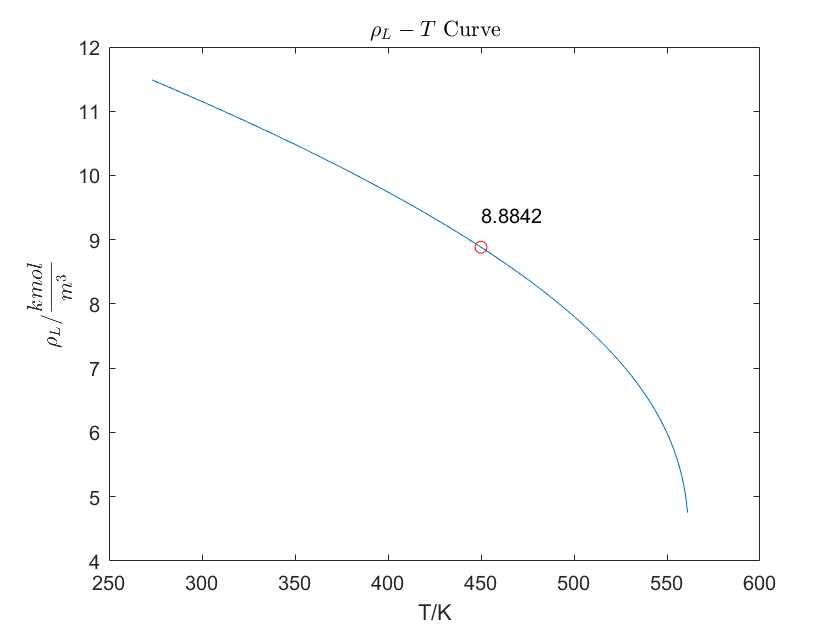

plot([ C6H6.IdealGasHeatCapacityCp(end-1):C6H6.IdealGasHeatCapacityCp(end) ], C6H6.IdealGasHeatCapacityCp_func( [C6H6.IdealGasHeatCapacityCp(end-1):C6H6.IdealGasHeatCapacityCp(end) ] ))
hold on

plot(450,  C6H6.IdealGasHeatCapacityCp_func(450), 'or')
text(455,  C6H6.IdealGasHeatCapacityCp_func(450), num2str(C6H6.IdealGasHeatCapacityCp_func(450)) )
hold off
title('$${C^{m,ideal}_{P,V}-T}$$ Curve', 'Interpreter', 'latex')
xlabel('T/K')
ylabel('$${C^m_{P,L}/ \frac{J}{kmol.K}}$$', 'Interpreter', 'latex')

- LiquidViscosity, 液体粘度, Pa.s

- 
$$\mu_L =e^{\left(A+\frac{B}{T}+\textrm{Cln}\left(T\right)+D*T^E \right)}$$


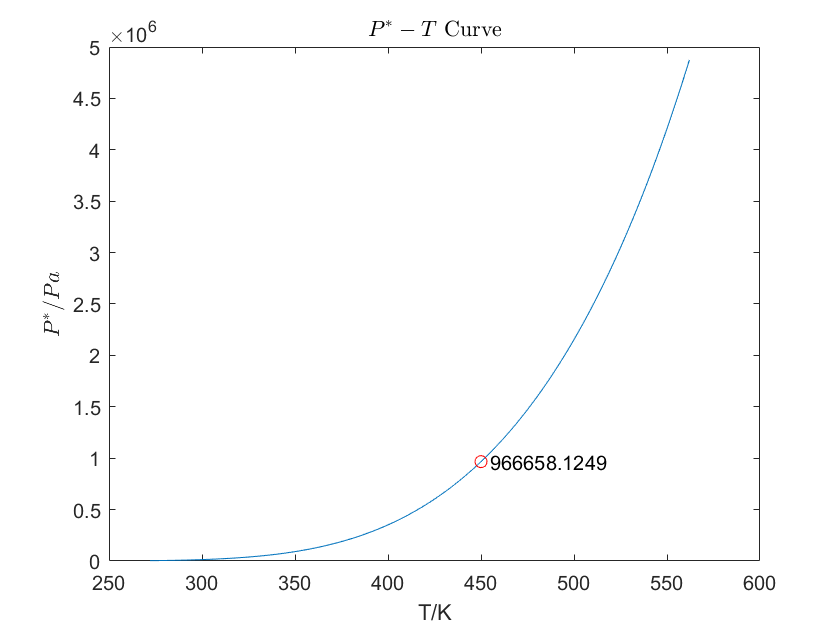

plot([ C6H6.LiquidViscosity(end-1):C6H6.LiquidViscosity(end) ], C6H6.LiquidViscosity_func( [ C6H6.LiquidViscosity(end-1):C6H6.LiquidViscosity(end) ] ))
hold on
plot(450,  C6H6.LiquidViscosity_func(450), 'or')

text(455,  C6H6.LiquidViscosity_func(450), num2str(C6H6.LiquidViscosity_func(450)) )
hold off
title('$${\mu_L-T}$$ Curve', 'Interpreter', 'latex')
xlabel('T/K')
ylabel('$${\mu_L/ Pa.S}$$', 'Interpreter', 'latex')

- VaporViscosity, 气体粘度, Pa.s

- 
$$\mu_V =\frac{A*T^B }{\left(1+\frac{C}{T}+\frac{D}{T^2 }\right)}$$


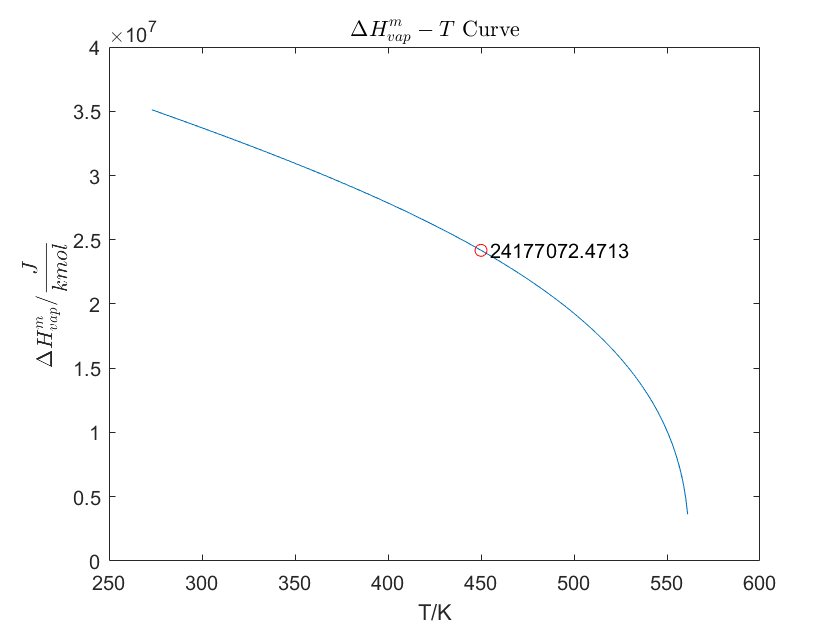

plot([ C6H6.VaporViscosity(end-1):C6H6.VaporViscosity(end) ], C6H6.VaporViscosity_func( [C6H6.VaporViscosity(end-1):C6H6.VaporViscosity(end) ] ))
hold on
plot(450,  C6H6.VaporViscosity_func(450), 'or')
text(455,  C6H6.VaporViscosity_func(450), num2str(C6H6.VaporViscosity_func(450)) )
hold off

title('$${\mu_V-T}$$ Curve', 'Interpreter', 'latex')
xlabel('T/K')
ylabel('$${\mu_V/ Pa.S}$$', 'Interpreter', 'latex')

- LiquidThermalConductivity, 液体导热系数, W/m/K

- 
$$\lambda_L =A+e^{\left(\frac{B}{T}+C+D*T+E*T^2 \right)}$$


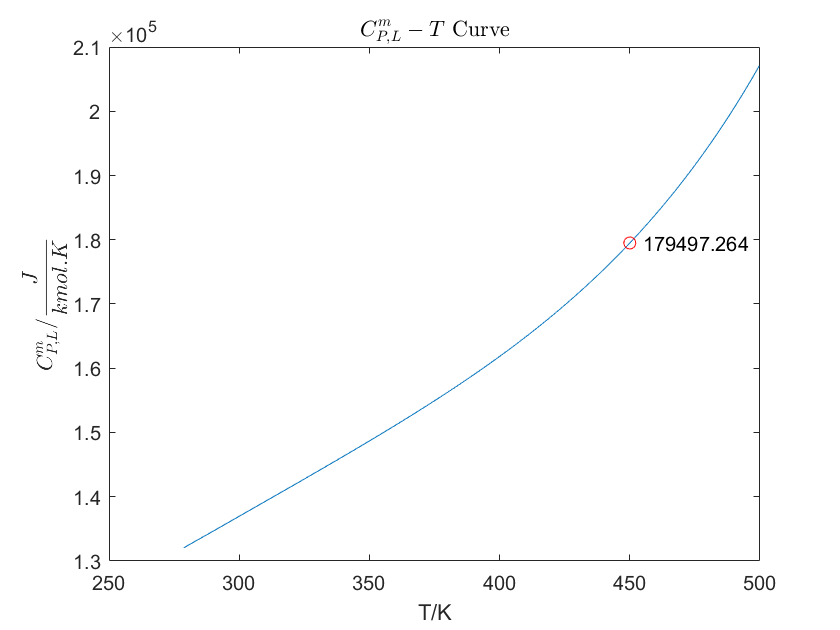

plot([ C6H6.LiquidThermalConductivity(end-1):C6H6.LiquidThermalConductivity(end) ], C6H6.LiquidThermalConductivity_func( [C6H6.LiquidThermalConductivity(end-1):C6H6.LiquidThermalConductivity(end) ] ))
hold on
plot(450,  C6H6.LiquidThermalConductivity_func(450), 'or')
text(455,  C6H6.LiquidThermalConductivity_func(450), num2str(C6H6.LiquidThermalConductivity_func(450)) )
hold off
title('$${\lambda_L-T}$$ Curve', 'Interpreter', 'latex')
xlabel('T/K')

ylabel('$${\lambda_L/ \frac{W}{m.K}}$$', 'Interpreter', 'latex')

- VaporThermalConductivity, 气体导热系数, W/m/K

- 
$$\lambda_V =\frac{A*T^B }{\left(1+\frac{C}{T}+\frac{D}{T^2 }\right)}$$


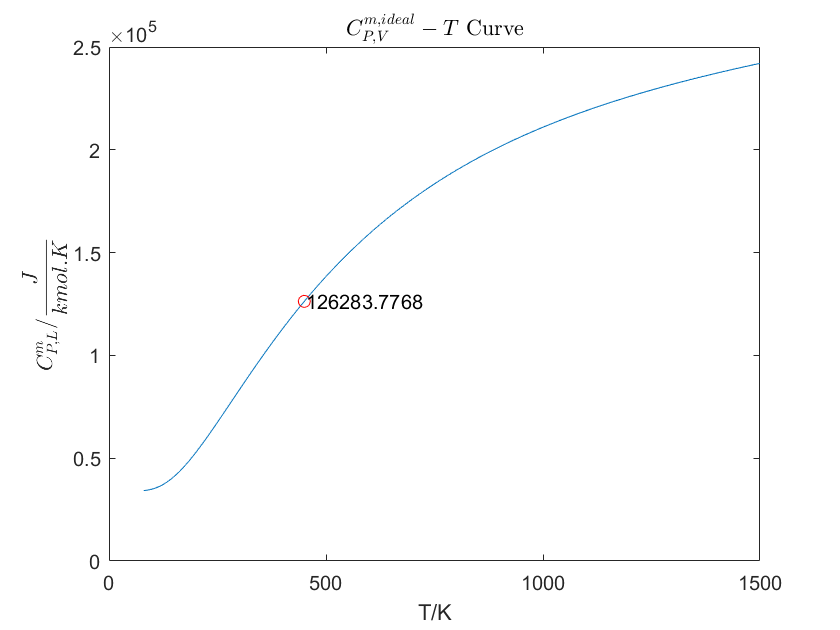

plot([ C6H6.VaporThermalConductivity(end-1):C6H6.VaporThermalConductivity(end) ], C6H6.VaporThermalConductivity_func( [C6H6.VaporThermalConductivity(end-1):C6H6.VaporThermalConductivity(end) ] ))
hold on
plot(450,  C6H6.VaporThermalConductivity_func(450), 'or')
text(455,  C6H6.VaporThermalConductivity_func(450), num2str(C6H6.VaporThermalConductivity_func(450)) )
hold off
title('$${\lambda_V-T}$$ Curve', 'Interpreter', 'latex')
xlabel('T/K')
ylabel('$${\lambda_V/ \frac{W}{m.K}}$$', 'Interpreter', 'latex')

- AntoineVaporPressure, 安托因蒸汽压, Pa

- 
$$P^{\textrm{Antoine}} =e^{\left(A-\frac{B}{\left(C+T\right)}\right)}$$


plot([ C6H6.AntoineVaporPressure(end-1):C6H6.AntoineVaporPressure(end) ], C6H6.AntoineVaporPressure_func( [C6H6.AntoineVaporPressure(end-1):C6H6.AntoineVaporPressure(end) ] ))
hold on
plot(450,  C6H6.AntoineVaporPressure_func(450), 'or')
text(455,  C6H6.AntoineVaporPressure_func(450), num2str(C6H6.AntoineVaporPressure_func(450)) )
hold off
title('$${P^Antoine-T}$$ Curve', 'Interpreter', 'latex')
xlabel('T/K')
ylabel('$${P^Antoine/ Pa}$$', 'Interpreter', 'latex')

- SurfaceTension, 表面张力, N/m

- 
$$\sigma \;=A+e^{\left(\frac{B}{T}+C+D*T+E*T^2 \right)}$$


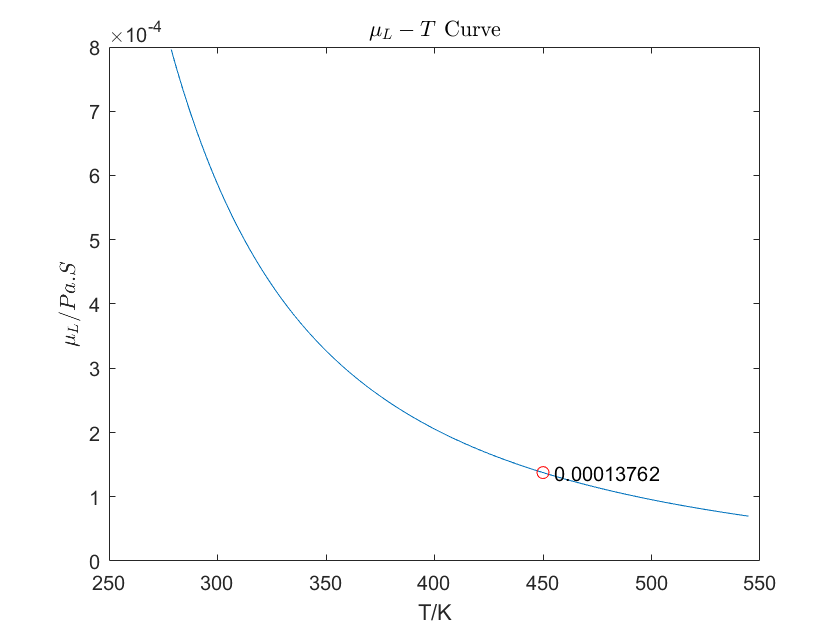

plot([ C6H6.SurfaceTension(end-1):C6H6.SurfaceTension(end) ], C6H6.SurfaceTension_func( [C6H6.SurfaceTension(end-1):C6H6.SurfaceTension(end) ] ))

hold on
plot(450,  C6H6.SurfaceTension_func(450), 'or')
text(455,  C6H6.SurfaceTension_func(450), num2str(C6H6.SurfaceTension_func(450)) )
hold off
title('$${\sigma-T}$$ Curve', 'Interpreter', 'latex')
xlabel('T/K')
ylabel('$${\sigma/ \frac{N}{m}}$$', 'Interpreter', 'latex')

纯物质,丙烷为例,计算体积

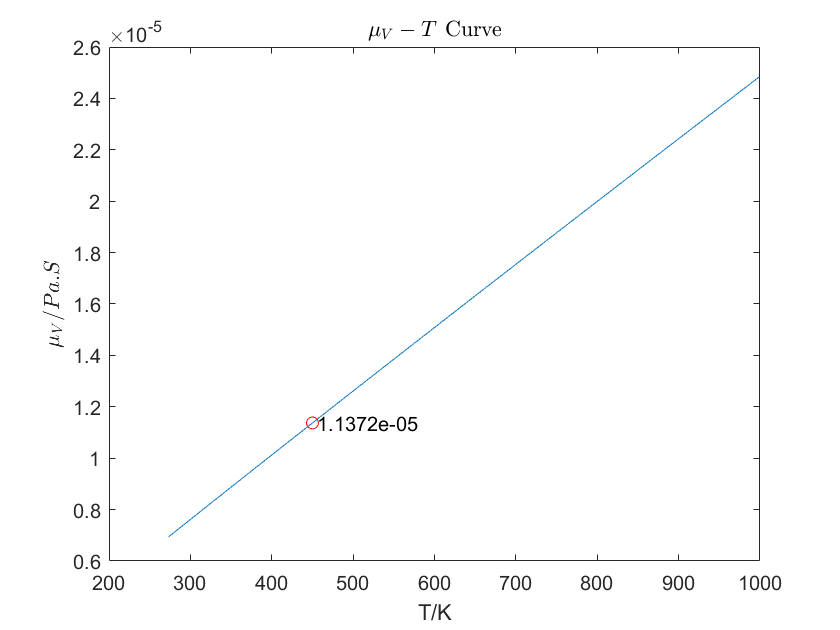

CAS = '74-98-6';
Propane = Component(CAS);

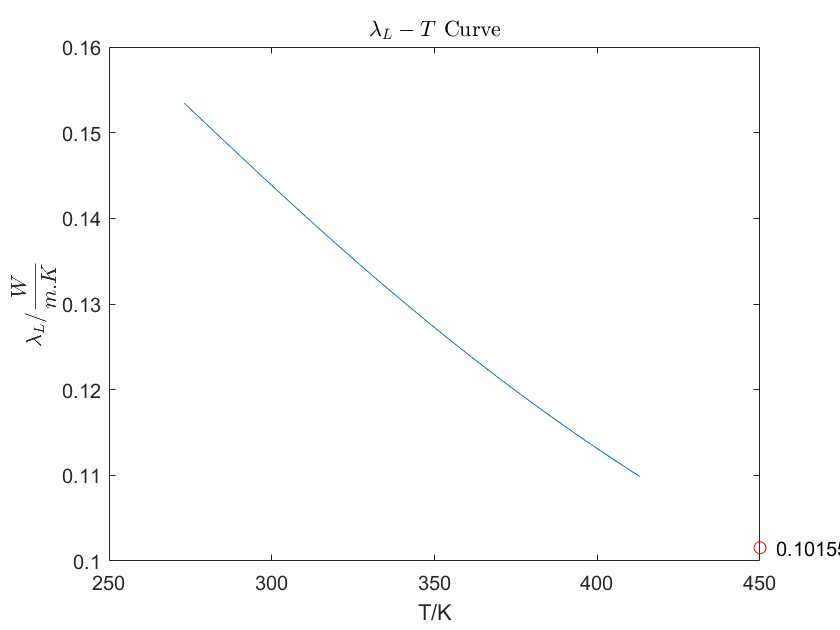

P = 997420;
T = 300;
z = 1;
q = 1;
Zl = EOS(P,T,z,q,Propane);
Vl = Zl*8.314*T/P
q = 0;
Zv = EOS(P,T,z,q,Propane);
Vv = Zv*8.314*T/P

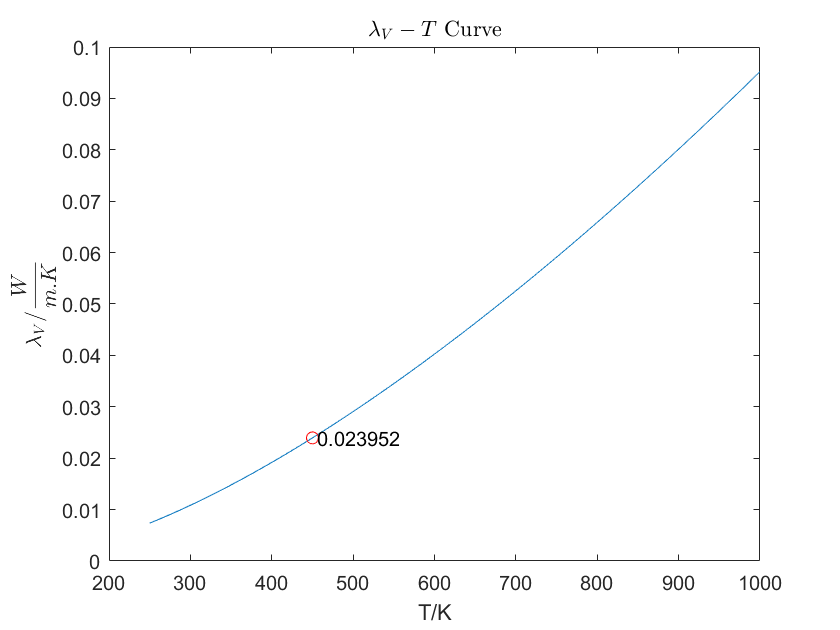

P = 4247700;
T =369.85;
q = 0;
Zcritical = EOS(P,T,z,q,Propane);
Vcritical = Zcritical*8.314*T/P

R12 = Propane;
R22 = Propane;
R12.Pc = 4.224*10^6;

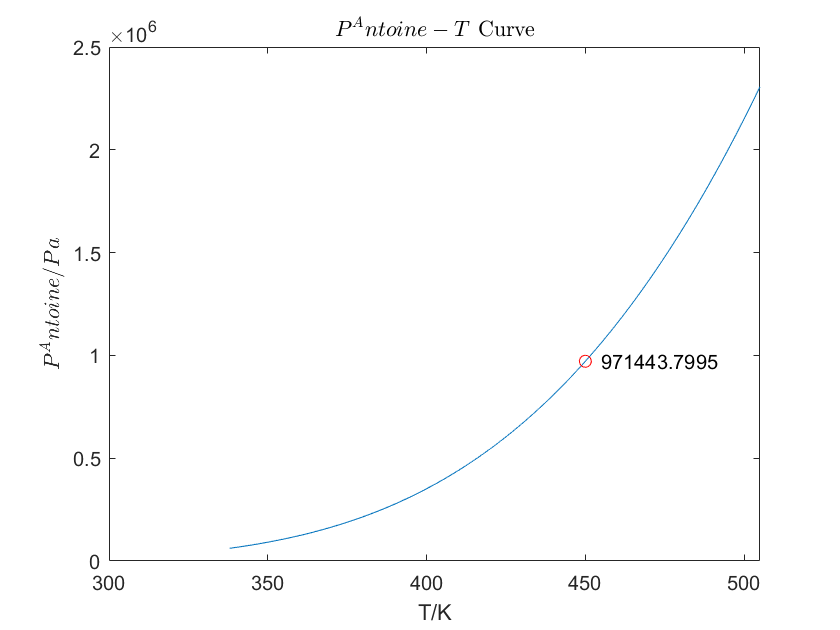

R12.Tc = 385;
R12.omega = 0.176;
R22.Pc = 4.975*10^6;
R22.Tc = 369.2;
R22.omega = 0.215;
P = 1.0*10^6;
T = 400;
q = 0;
z = [0.5,0.5];

for P = [1:5]*10^6
    Zv = EOS(P,T,z,q,[R22,R12])
    Vv = Zv*8.314*T/P
end

混合物,R12(CCl2F2)和R22(CHClF2为例,计算体积

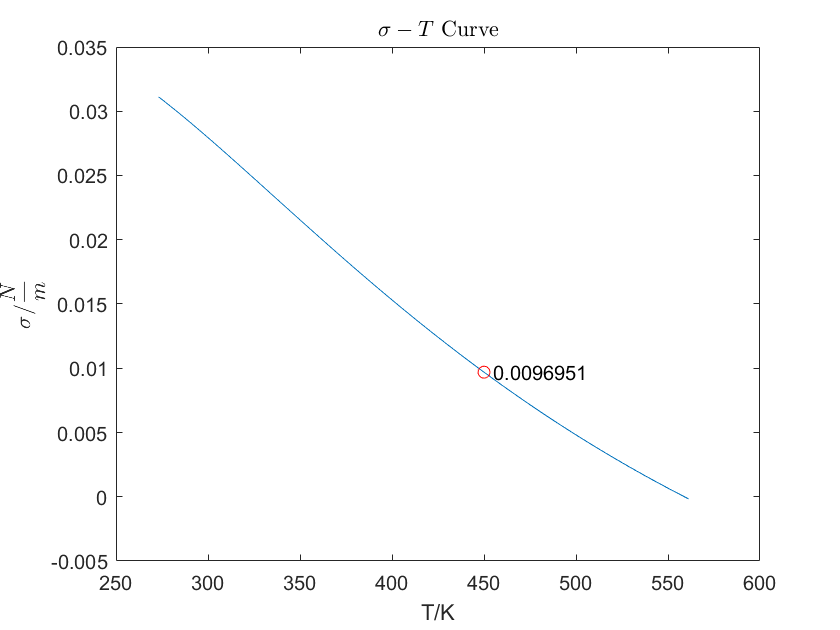

R12 = Propane;
R22 = Propane;
R12.Pc = 4.224*10^6;
R12.Tc = 385;
R12.omega = 0.176;

R22.Pc = 4.975*10^6;
R22.Tc = 369.2;
R22.omega = 0.215;
P = 1.0*10^6;
T = 400;
q = 0;
z = [0.5,0.5];
for P = [1:5]*10^6
    Zv = EOS(P,T,z,q,[R22,R12])

Vl =      8.676502462792916e-05


    Vv = Zv*8.314*T/P
end

function Property = Component(CAS)

Vv =    0.002038518631244


    CAS = [CAS, '.json'];
    PropertyParameter = jsondecode(fileread(CAS));

    Property.CAS = PropertyParameter.CAS;
    Property.Ename = PropertyParameter.CompoundID;

Vcritical =      2.414393810261508e-04


    Property.StructureFormula = PropertyParameter.StructureFormula;

    % Pc, 临界压力, Pa
    Property.Pc = str2double(PropertyParameter.CriticalPressure(1));
    % Tc, 临界温度, K    
    Property.Tc = str2double(PropertyParameter.CriticalTemperature(1));
    % Vc, 临界体积, m3/kmol
    Property.Vc = str2double(PropertyParameter.CriticalVolume(1));
    % Zc, 临界压缩因子, -
    Property.Zc = str2double(PropertyParameter.CriticalCompressibility(1));
    % Tb, 常压沸点温度, K
    Property.Tb = str2double(PropertyParameter.NormalBoilingPointTemperature(1));
    % Ttriple, 三相点温度, K
    Property.Ttriple = str2double(PropertyParameter.TriplePointTemperature(1));
    % Ptriple, 三相点压力, Pa
    Property.Ptriple = str2double(PropertyParameter.TriplePointPressure(1));
    % Mw, 摩尔质量, kg/kmol

Zv =    0.928653697117342


Vv =    0.003088330735133


Zv =    0.852546345387205


Vv =    0.001417614063110


Zv =    0.769907552167168


Vv =      8.534681851623783e-04


Zv =    0.677720872158938


Vv =      5.634571331129412e-04


Zv =    0.570682190200430


Vv =      3.795721383461101e-04


    Property.Mw = str2double(PropertyParameter.MolecularWeight(1));
    % omega, 偏心因子, -
    Property.omega = str2double(PropertyParameter.AcentricityFactor(1));
    % Hform, 标准摩尔生成焓, J/kmol
    Property.Hform = str2double(PropertyParameter.HeatOfFormation(1));
    % Gform, 标准摩尔生成自由能, J/kmol
    Property.Gform = str2double(PropertyParameter.GibbsEnergyOfFormation(1));
    
    % LiquidDensity, 液体的密度, kmol/m3
    % LiquidDensity_func, DIPPR函数
    PropertyName = 'LiquidDensity';
    group = PropertyParameter.LiquidDensity(1);
    equationNo = group{1}.eqno;
    [Property.LiquidDensity, Property.LiquidDensity_func] = DIPPR(equationNo);
    
    % VaporPressure, 饱和蒸汽压, Pa
    % VaporPressure_func, DIPPR函数
    PropertyName = 'VaporPressure';
    group = PropertyParameter.VaporPressure(1);
    equationNo = group{1}.eqno;
    [Property.VaporPressure, Property.VaporPressure_func] = DIPPR(equationNo);
    
    % HeatOfVaporization, 标准摩尔蒸发焓, J/kmol
    % HeatOfVaporization_func, DIPPR函数
    PropertyName = 'HeatOfVaporization';
    group = PropertyParameter.HeatOfVaporization(1);
    equationNo = group{1}.eqno;
    [Property.HeatOfVaporization, Property.HeatOfVaporization_func] = DIPPR(equationNo);
    
    % LiquidHeatCapacityCp, 液体等压比热容, J/kmol/K
    % LiquidHeatCapacityCp_func, DIPPR函数
    PropertyName = 'LiquidHeatCapacityCp';
    group = PropertyParameter.LiquidHeatCapacityCp(1);
    equationNo = group{1}.eqno;
    [Property.LiquidHeatCapacityCp, Property.LiquidHeatCapacityCp_func] = DIPPR(equationNo);
    
    % IdealGasHeatCapacityCp, 理想气体等压比热容, J/kmol/K
    % IdealGasHeatCapacityCp_func, DIPPR函数
    PropertyName = 'IdealGasHeatCapacityCp';
    group = PropertyParameter.IdealGasHeatCapacityCp(1);
    equationNo = group{1}.eqno;
    [Property.IdealGasHeatCapacityCp, Property.IdealGasHeatCapacityCp_func] = DIPPR(equationNo);
    
    % LiquidViscosity, 液体粘度, Pa.s
    % LiquidViscosity, DIPPR函数
    PropertyName = 'LiquidViscosity';
    group = PropertyParameter.LiquidViscosity(1);
    equationNo = group{1}.eqno;
    [Property.LiquidViscosity, Property.LiquidViscosity_func] = DIPPR(equationNo);
    
    % VaporViscosity, 气体粘度, Pa.s
    % VaporViscosity_func, DIPPR函数
    PropertyName = 'VaporViscosity';
    group = PropertyParameter.VaporViscosity(1);
    equationNo = group{1}.eqno;
    [Property.VaporViscosity, Property.VaporViscosity_func] = DIPPR(equationNo);
    
    % LiquidThermalConductivity, 液体导热系数, W/m/K
    % LiquidThermalConductivity_func, DIPPR函数
    PropertyName = 'LiquidThermalConductivity';
    group = PropertyParameter.LiquidThermalConductivity(1);
    equationNo = group{1}.eqno;
    [Property.LiquidThermalConductivity, Property.LiquidThermalConductivity_func] = DIPPR(equationNo);
    
    % VaporThermalConductivity, 气体导热系数, W/m/K
    % VaporThermalConductivity_func, DIPPR函数
    PropertyName = 'VaporThermalConductivity';
    group = PropertyParameter.VaporThermalConductivity(1);
    equationNo = group{1}.eqno;
    [Property.VaporThermalConductivity, Property.VaporThermalConductivity_func] = DIPPR(equationNo);
    
    % AntoineVaporPressure, 安托因蒸汽压, Pa
    % AntoineVaporPressure_func, DIPPR函数
    PropertyName = 'AntoineVaporPressure';
    group = PropertyParameter.AntoineVaporPressure(1);
    equationNo = group{1}.eqno;
    [Property.AntoineVaporPressure, Property.AntoineVaporPressure_func] = DIPPR(equationNo);
    
    
    % SurfaceTension, 表面张力, N/m
    % SurfaceTension_func, DIPPR函数
    PropertyName = 'SurfaceTension';
    group = PropertyParameter.SurfaceTension(1);
    equationNo = group{1}.eqno;
    [Property.SurfaceTension, Property.SurfaceTension_func] = DIPPR(equationNo);
    
    function [para, func] = DIPPR(equationNo)
        equation = PropertyParameter.(PropertyName)(1);
        Tmin = str2double(equation{1}.Tmin);
        Tmax = str2double(equation{1}.Tmax);
        switch equationNo
            case '1'
                A = str2double(equation{1}.A);
                para = [A,Tmin,Tmax];
                func = @(T) A;
            case '2'
                A = str2double(equation{1}.A);
                B = str2double(equation{1}.B);
                para = [A,B,Tmin,Tmax];
                func = @(T) A + B.*T;
            case '3'
                A = str2double(equation{1}.A);
                B = str2double(equation{1}.B);
                C = str2double(equation{1}.C);
                para = [A,B,C,Tmin,Tmax];
                func = @(T) A + B.*T + C.*T.^2;
            case '4'
                A = str2double(equation{1}.A);
                B = str2double(equation{1}.B);
                C = str2double(equation{1}.C);
                D = str2double(equation{1}.D);
                para = [A,B,C,D,Tmin,Tmax];
                func = @(T) A + B.*T + C.*T.^2 + D.*T.^3;
            case '5'
                A = str2double(equation{1}.A);
                B = str2double(equation{1}.B);
                C = str2double(equation{1}.C);
                D = str2double(equation{1}.D);
                E = str2double(equation{1}.E);
                para = [A,B,C,D,E,Tmin,Tmax];
                func = @(T) A + B.*T + C.*T.^2 + D.*T.^3 + E.*T.^4;
            case '6'
                A = str2double(equation{1}.A);
                B = str2double(equation{1}.B);
                C = str2double(equation{1}.C);
                D = str2double(equation{1}.D);
                E = str2double(equation{1}.E);
                para = [A,B,C,D,E,Tmin,Tmax];
                func = @(T) A + B.*T + C.*T.^2 + D.*T.^3 + E./T.^2;
            case '10'
                A = str2double(equation{1}.A);
                B = str2double(equation{1}.B);
                C = str2double(equation{1}.C);
                para = [A,B,C,Tmin,Tmax];
                func = @(T) exp(A - B./(C+T)); 
            case '16'
                A = str2double(equation{1}.A);
                B = str2double(equation{1}.B);
                C = str2double(equation{1}.C);
                D = str2double(equation{1}.D);
                E = str2double(equation{1}.E);
                para = [A,B,C,D,E,Tmin,Tmax];
                func = @(T) A + exp(B./T + C + D*T + E.*T.^2);
            case '100'
                A = str2double(equation{1}.A);
                B = str2double(equation{1}.B);
                C = str2double(equation{1}.C);
                D = str2double(equation{1}.D);
                E = str2double(equation{1}.E);
                para = [A,B,C,D,E,Tmin,Tmax];
                func = @(T) A + B.*T + C.*T.^2 + D.*T.^3 + E.*T.^4;
            case '101'
                A = str2double(equation{1}.A);
                B = str2double(equation{1}.B);
                C = str2double(equation{1}.C);
                D = str2double(equation{1}.D);
                E = str2double(equation{1}.E);
                para = [A,B,C,D,E,Tmin,Tmax];
                func = @(T) exp(A + B./T + C.*log(T) + D.*T.^E);
            case '102'
                A = str2double(equation{1}.A);
                B = str2double(equation{1}.B);
                C = str2double(equation{1}.C);
                D = str2double(equation{1}.D);
                para = [A,B,C,D,Tmin,Tmax];
                func = @(T) A.*T.^B./(1 + C./T + D./T.^2);
            case '103'
                A = str2double(equation{1}.A);
                B = str2double(equation{1}.B);
                C = str2double(equation{1}.C);
                D = str2double(equation{1}.D);
                para = [A,B,C,D,Tmin,Tmax];
                func = @(T) A + B.*exp(-C./T.^D);
            case '104'
                A = str2double(equation{1}.A);
                B = str2double(equation{1}.B);
                C = str2double(equation{1}.C);
                D = str2double(equation{1}.D);
                E = str2double(equation{1}.E);
                para = [A,B,C,D,E,Tmin,Tmax];
                func = @(T) A + B./T + C*10^6./T.^3 + D*10^16./T.^8 + E*10^18./T.^9;
            case '105'
                A = str2double(equation{1}.A);
                B = str2double(equation{1}.B);
                C = str2double(equation{1}.C);
                D = str2double(equation{1}.D);
                para = [A,B,C,D,Tmin,Tmax];
                func = @(T) A./B.^(1+(1-T/C).^D);
            case '106'
                A = str2double(equation{1}.A);
                B = str2double(equation{1}.B);
                C = str2double(equation{1}.C);
                D = str2double(equation{1}.D);
                E = str2double(equation{1}.E);
                para = [A,B,C,D,E,Tmin,Tmax];
                func = @(T) A.*(1-T./Property.Tc).^(B + C.*(T./Property.Tc) + D.*(T./Property.Tc).^2 + E.*(T./Property.Tc).^3);
            case '107'
                A = str2double(equation{1}.A);
                B = str2double(equation{1}.B);
                C = str2double(equation{1}.C);
                D = str2double(equation{1}.D);
                E = str2double(equation{1}.E);
                para = [A,B,C,D,E,Tmin,Tmax];
                func = @(T) A + B.*(C./T./sinh(C./T)).^2 + E.*(D./T./cosh(D./T)).^2;
            case '114'
                A = str2double(equation{1}.A);
                B = str2double(equation{1}.B);
                C = str2double(equation{1}.C);
                D = str2double(equation{1}.D);
                para = [A,B,C,D,Tmin,Tmax];
                func = @(T) A.*T + B.*T.^2/2 + C.*T.^3/3 + D.*T.^4/4;
            case '117'
                A = str2double(equation{1}.A);
                B = str2double(equation{1}.B);
                C = str2double(equation{1}.C);
                D = str2double(equation{1}.D);
                E = str2double(equation{1}.E);
                para = [A,B,C,D,E,Tmin,Tmax];
                func = @(T) A.*T + B.*(C./T)./tanh(C./T) - D.*(E./T)./tanh(E./T);
        end   
    end
    
end

function Z = EOS(P,T,z,q,Component)
    % Constant;
    R = 8.314;
    c = length(z);
    z = z./sum(z);
    Pc = ones(c,1);
    Tc = ones(c,1);
    omega = ones(c,1);
    Mw = ones(c,1);
    for i = 1:c
        Pc(i) = Component(i).Pc;
        Tc(i) = Component(i).Tc;
        omega(i) = Component(i).omega;
        Mw(i) = Component(i).Mw;
    end
    
    % PR 方程系数
    Omega_a = 0.45724;
    Omega_b = 0.0778;
    m = [0.37464, 1.54226, -0.2699];
    
    alpha = (1+ (m(1) + m(2).*omega + m(3).*omega.^2).*(1-(T./Tc).^0.5) ).^2;
    a_i = Omega_a.*R.^2.*Tc.^2./Pc .* alpha; 
    b_i = Omega_b*R.*Tc./Pc;
    a = MixRule(z,a_i,0,2);
    b = MixRule(z,b_i,0,1);
    
    % PR 方程关系式
    B = b*P/R/T;
    delta = 2*B;
    varepsilon = -B^2;
    eta = B;
    A = a*P/(R*T)^2;
    
    EOS_coeff = [1, delta-B-1, A+varepsilon-delta*(B+1), -(varepsilon*(B+1)+A*eta)];
    Z = roots(EOS_coeff);
    Z = Z(imag(Z) == 0);
    
    % q, 液相分率, [0,1]
    if q == 1
        Z = min(Z);
    elseif q == 0
        Z = max(Z);
    end
    
    function Q = MixRule(z,Q_i,kij,rule)
        % z, 为摩尔组成, 1*c
        % Q_i, 为物性参数量, c*1
        % rule, 混合规则
        % kij, 二元交互参数, c*c
        % 一般情况下, 默认i=j时, kij = 0;
        if nargin == 3
            kij = 0;
        end
        
        switch rule
            case 1
                Q = z*Q_i;
            case 2
                Q = z*( (Q_i*Q_i').^0.5 ).*(1-kij)*z';
        end
        
    end
    
end
